# Guide for mini workshop on QPSK Transmitter and Receiver

## Part 1 - First startup

When first opening the model `commqpsktxrx_start.slx`, you'll notice that there are some blocks that are highlighted in red

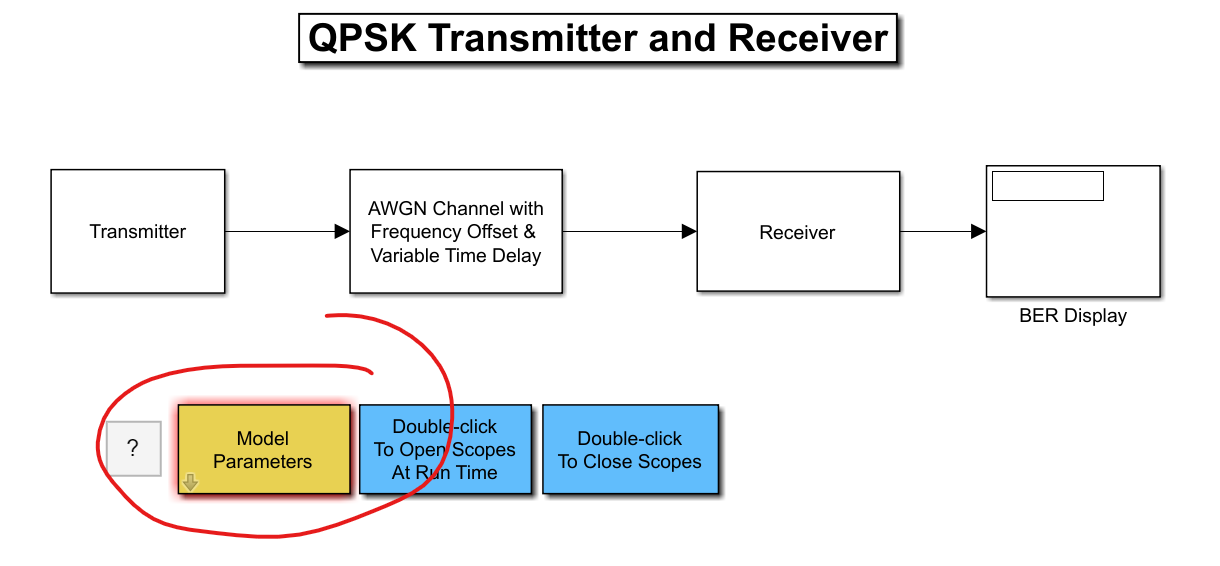

That's because the blocks are using variables, which have not been initialised yet

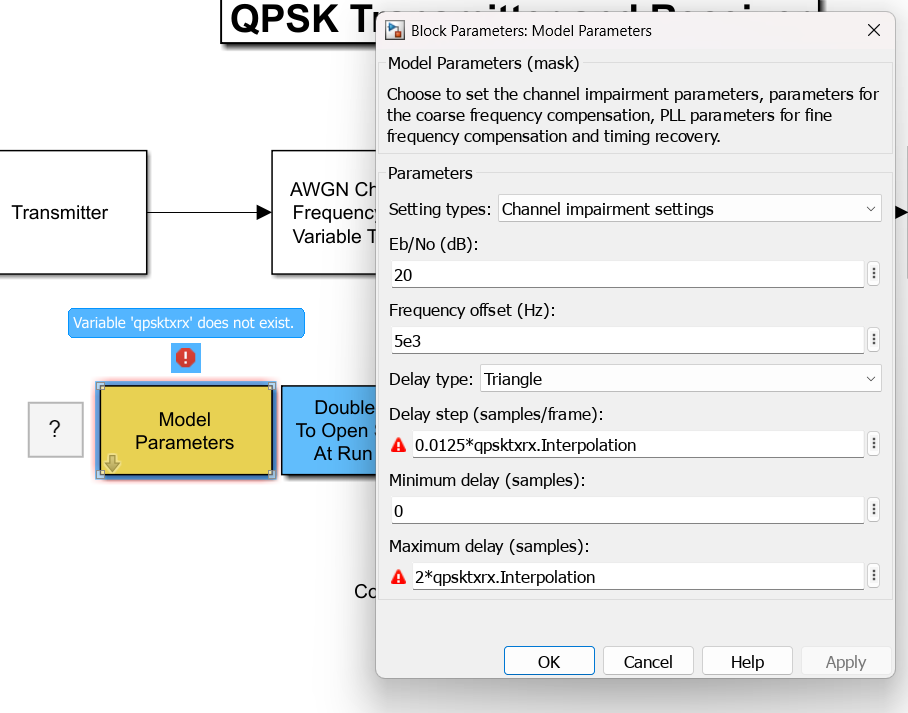

## Part 2 - Model Callbacks

To initialise the variables, we will use callbacks to run the file below. Run the code below in the Command Window to display the file.

Since there are many calculations derives from "system" variables, it is better to use a script to define variables so that you do not need to change multiple variables across the entire model if any changes were to be made.

Go go `Modeling` > `Model Settings` > `Model Properties`

In `PreLoadFcn` and `PostLoadFcn`, insert

In `StopFcn`, insert

## Part 3 - Solver Setup 

One of the more important things when it comes to comms simulations is the solver

Since comms systems are discrete in nature, the simulations steps should also be discrete. Set

- **Type**: `Fixed-step`

- **Solver**: `discrete (no continuous states)`

- **Fixed-step size**: `auto`

For the simulation **Stop time**, we can calculate it using the number of frames and the duration of each frame 

Remeber to press **Apply**!

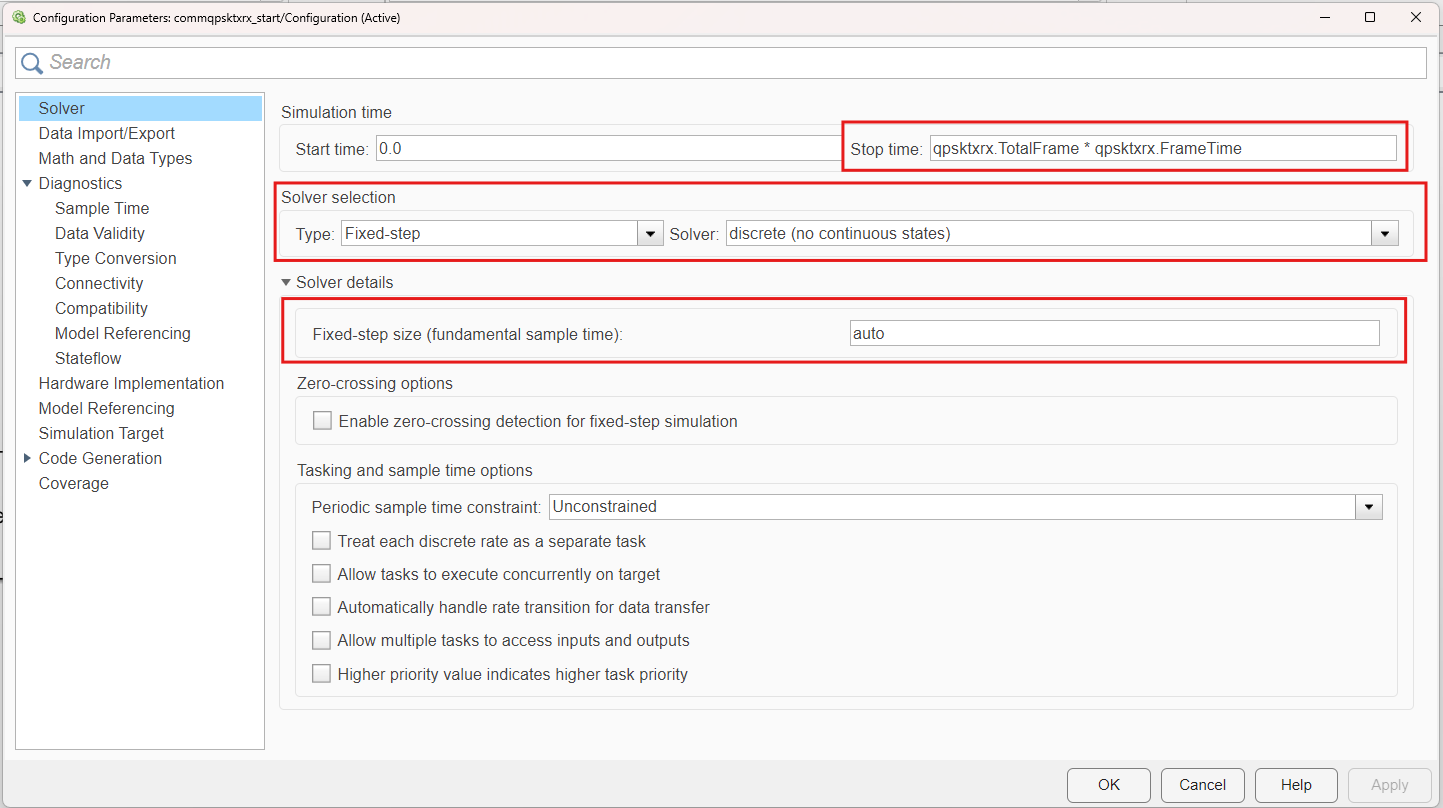

## Part 4 - Transmitter

Can refer to the [example documentation](matlab:open('./QPSKTransmitterAndReceiverSimulinkExample.mlx')) for more detail.

### Bit Generation

Go to **Transmitter** > **Bit Generation**. Explain how it works.

- the message bits are taken from the workspace

- which is then packaged into "frames", or "packets"

- the bits within the frame are scrambled

- the frame is then sandwiched (concatenated) between two unipolar barker code for synchronization at the receiver side

### Raised Cosine Filter

Go to **Transmitter** subsystem. Create a **Raised Cosine Transmit Filter **(Library > Communications Tool > Comm Filters)

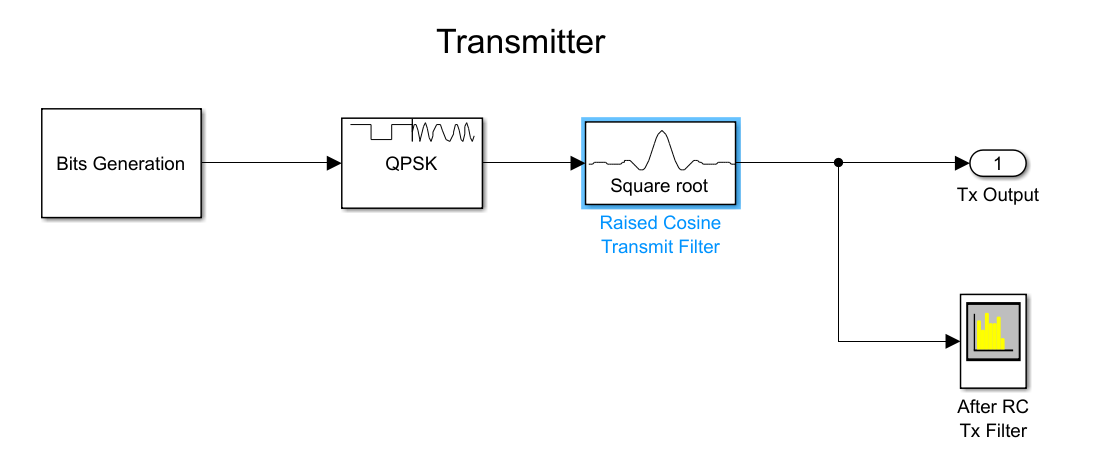

We are doing a frame-based simulation. Use the following settings:

- **Filter shape**: `Square root`

- **Rolloff factor**: `qpsktxrx.RolloffFactor`

- **Filter span in symbols**: `qpsktxrx.RaisedCosineFilterSpan`

- **Output samples per symbol**: `qpsktxrx.Interpolation`

- **Linear amplitude filter gain**: `1`

- **Input processing**: `Column as channels (frame based)`

- **Rate options**: `Enforce single-rate processing`

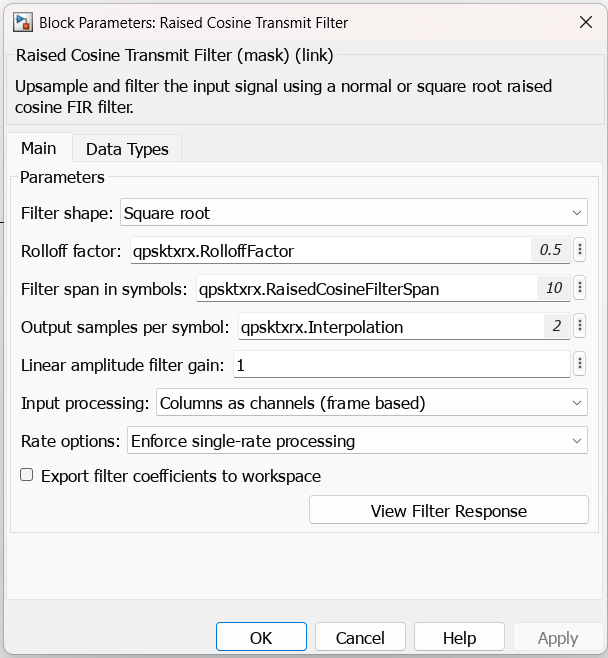

You can view the filter response as well

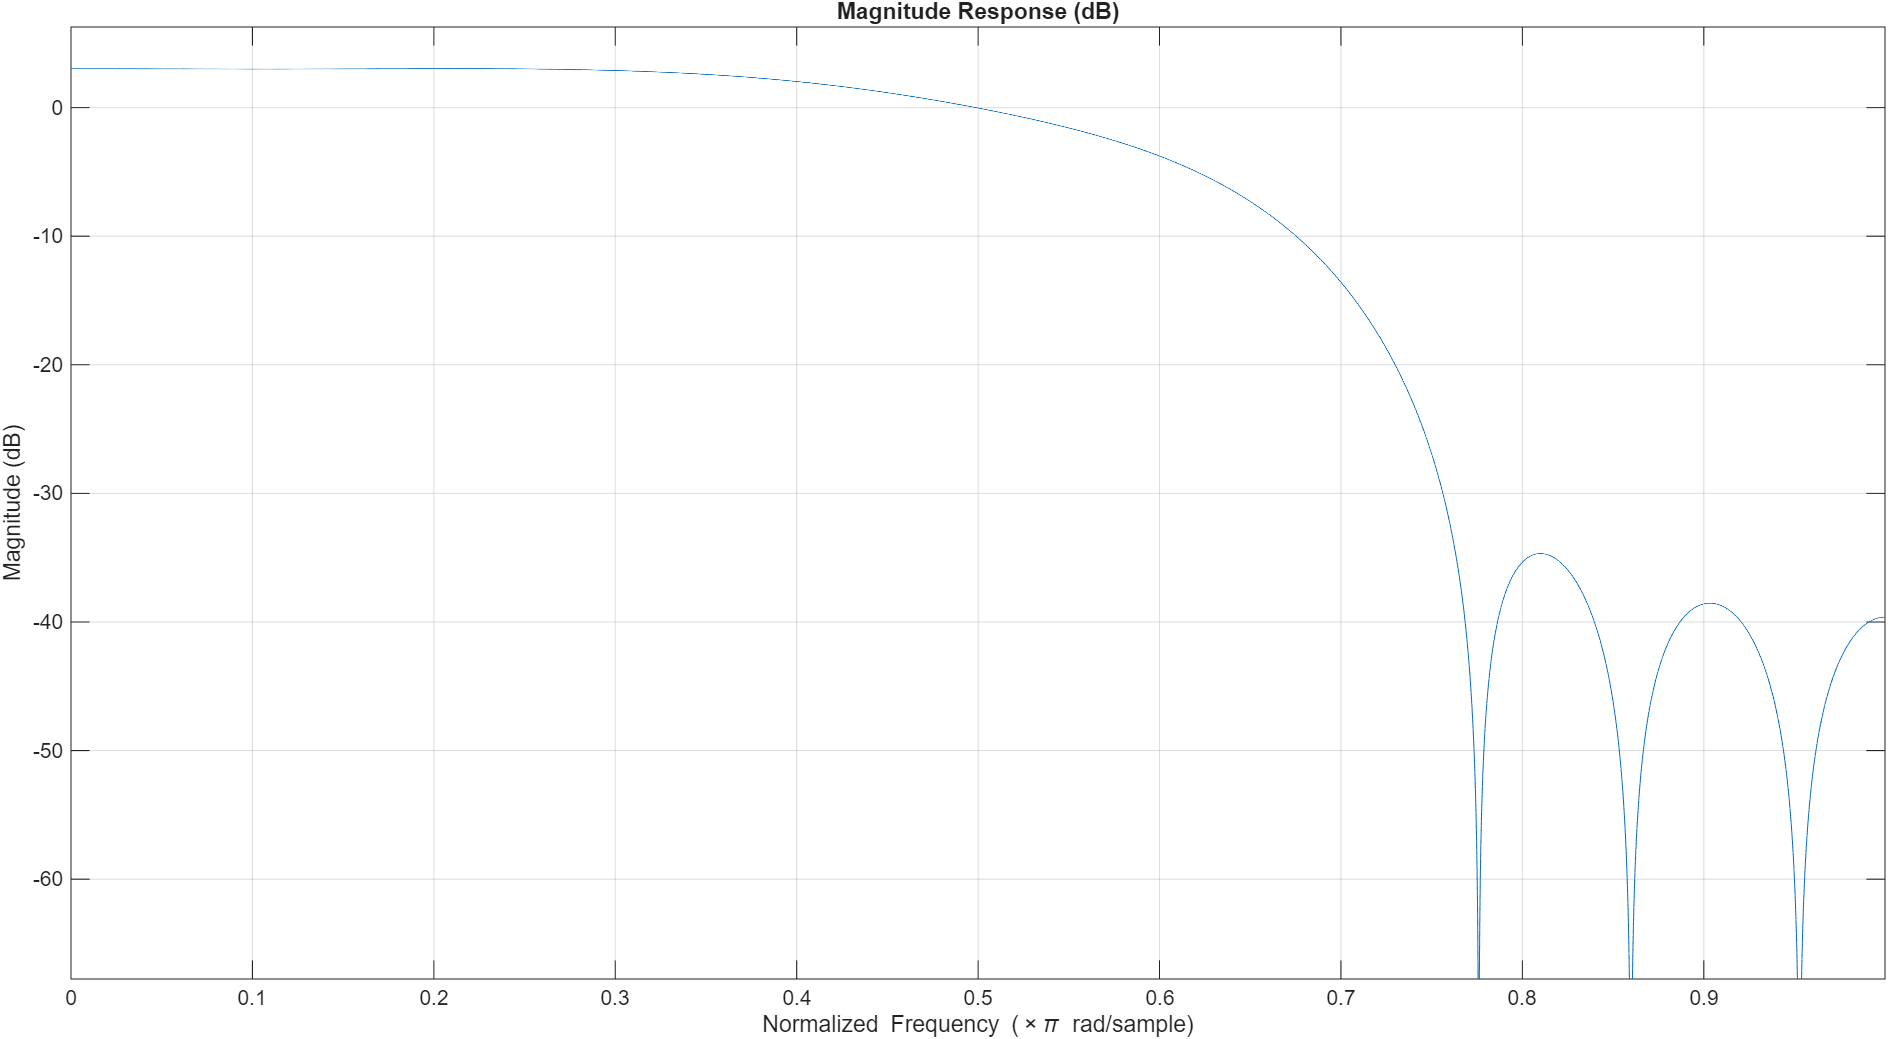

## Part 5 - Channel Modelling

Can refer to the [example documentation](matlab:open('./QPSKTransmitterAndReceiverSimulinkExample.mlx')) for more detail.

### AWGN Channel

Go to the **AWGN Channel...** subsystem. Here, we attempt to model a somewhat realistic channel to test the receiver.

Create a AWGN Channel block (Library > Communications Tool > Channels)

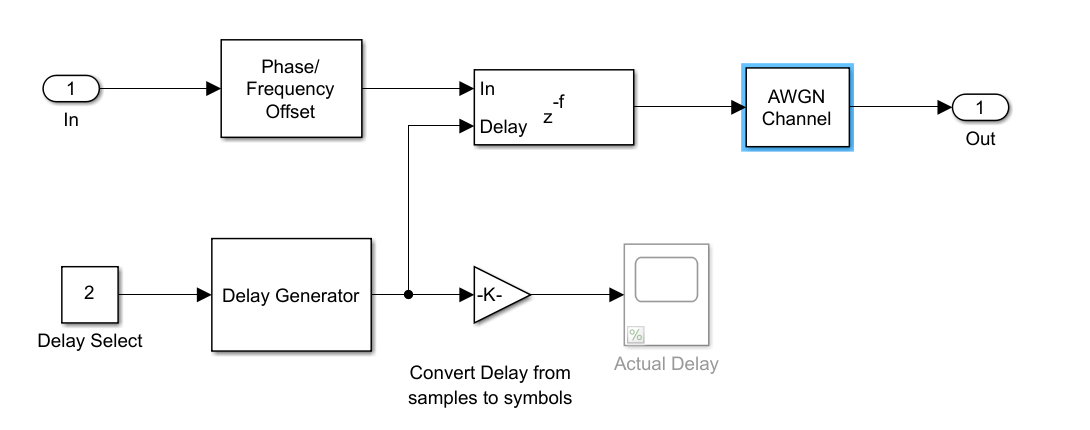

Use the following settings:

- **Mode**: `Signal to noise ratio (Eb/No)`

- **Eb/No (dB)**: `20`

- **Number of bits per symbol**: `log2(qpsktxrx.ModulationOrder)`

- **Input signal power...**: `1/qpsktxrx.Interpolation`

- **Samples per symbol**: `round(qpsktxrx.Tsym / 1.000000e-05)`

- **Random number source**: `mt199937ar with seed`

- **Initial seed**: `2`

- **Simulate using**: `Code generation`

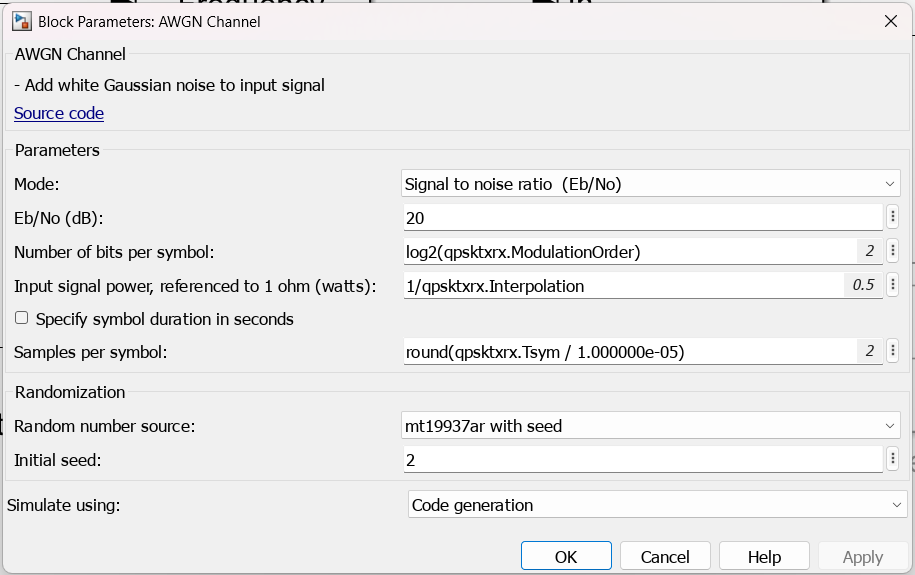

### Explain

Explain the following:

- The Phase/Frequency Offset block gives a fixed phase and frequency offset

- The Delay Generator creates a delay that increase and decreases, scaling using a triangule wave

- The AWGN Channel models white noise

## Part 6 - Receiver

For this part, *definitely* refer to the [example documentation](matlab:open('./QPSKTransmitterAndReceiverSimulinkExample.mlx')) for more detail.

### Symbol Synchronizer

Go to the **Receiver** subsystem. Here, we attempt to model a** practical receiver that can compensate for impairments**.

Create a Symbol Synchronizer block (Library > Communications Tool > Synchronization)

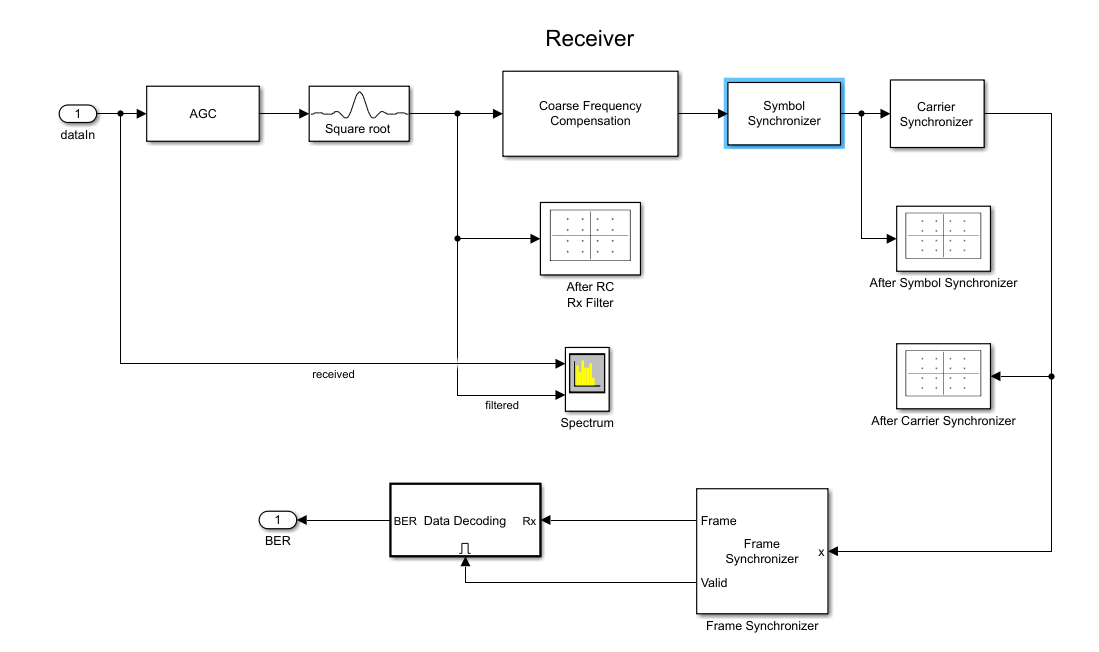

Use the following settings:

- **Modulation type**: `PAM/PSK/QAM`

- **Timing error detector method**: `Gardner (non-data-aided)`

- **Symbols per symbol**: `qpsktxrx.Interpolation/qpsktxrx.Decimation`

- **Damping factor of loop filter**: `1`

- **Normalized bandwidth of loop filter**: `0.01`

- **Phase detector gain**: `qpsktxrx.TimingErrorDetectorGain`

- **Simulate using**: `Code generation`

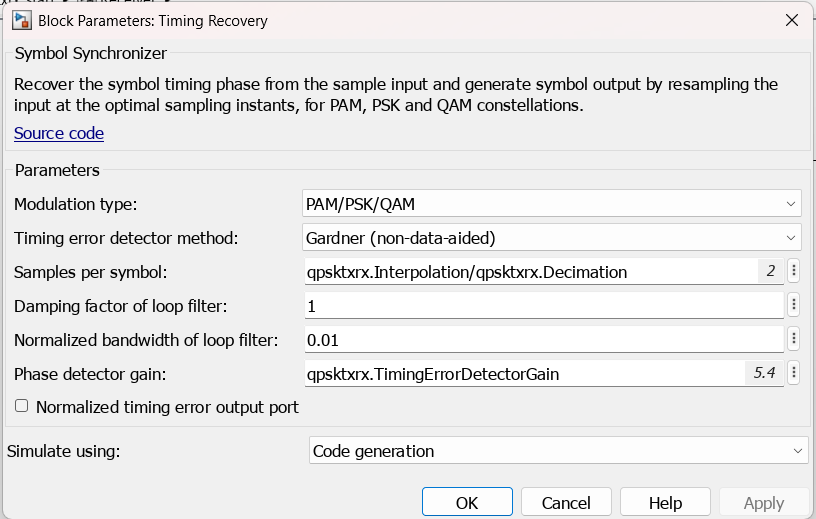

## Bonus: Block double-click callback

You can make an "empty block", that once double-clicked, can run code using callbacks.

Go to the `properties` of the "Double-click to open scopes at run time" block, and navigate to `Callback` >` OpenFcn`.